## Assignment 2

Load in both images to be used for testing throughout the assignment.

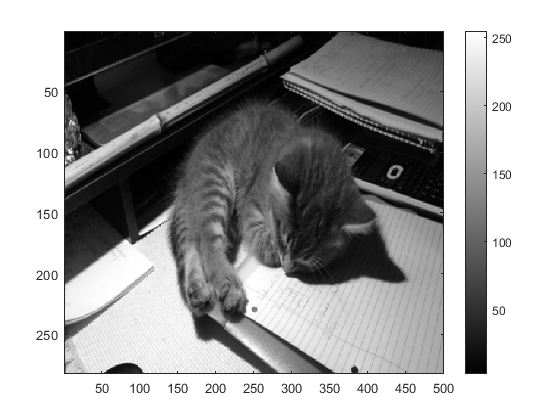

clear
naturalIm = rgb2gray(imread("MyKitten.jpg"));
naturalIm = imresize(naturalIm, [NaN 500]);
artificialIm = rgb2gray(imread("Artificial.png")); %Already sized 400x400

colormap(gray);
imagesc(naturalIm);
colorbar

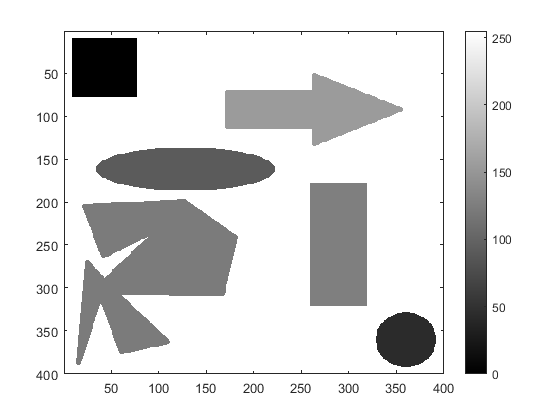

imagesc(artificialIm);
colorbar

### Question 1: Gaussian scale space [10 points]

For gaussian scale space going from sigma-not to 16*sigma-not with the logarithmic incremental growth we'd require that the scale space starts at sigma-not and grows as (2^((h/m)+k)*sigma-not where h, m, and k are all integers, for m = 4, k going from 0 to 3, and h going from 1 to m.

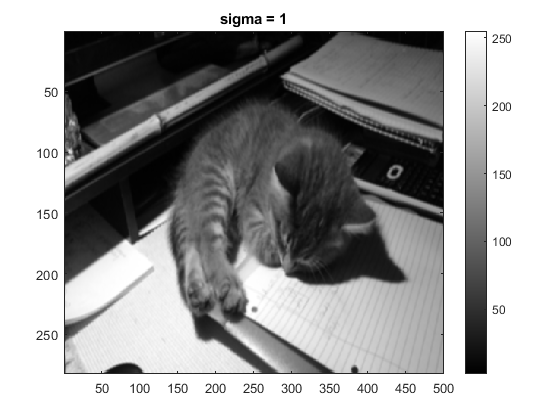

sigmaNot = 1; %Play with this value to see different results
upperLimit = 16; %Must be some number 2^n for n >= 0 integer.

[gaussScaleNaturalIms, naturalSigmas] = gaussianScaleSpace(naturalIm, upperLimit, sigmaNot);
imagesc(gaussScaleNaturalIms(:, :, 1));
colorbar
title("sigma = " + naturalSigmas(:, 1));

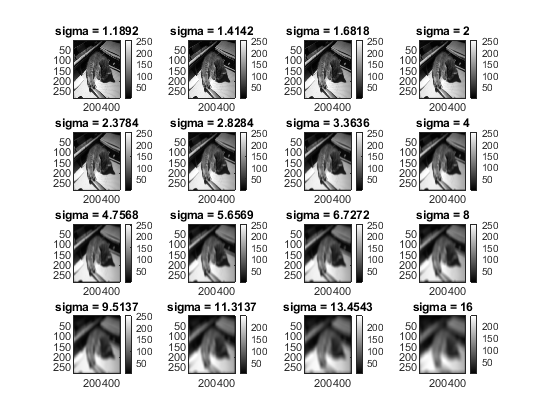

stride = 1;
subPlotShape = sqrt(upperLimit);
for i = 1:stride:upperLimit
    subplot(subPlotShape, subPlotShape, i);
    imagesc(gaussScaleNaturalIms(:, :, i+1));
    colorbar
    title("sigma = " + naturalSigmas(:, i+1));
end

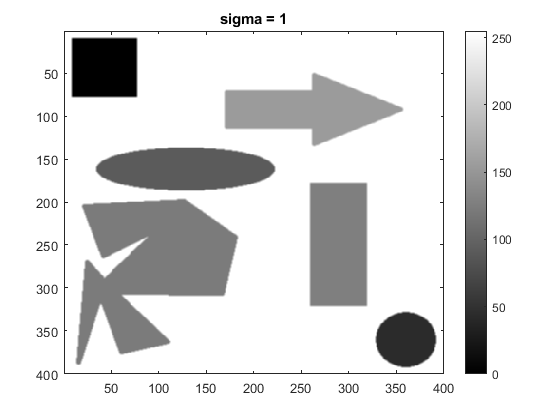

[gaussScaleArtificialIms, artificialSigmas] = gaussianScaleSpace(artificialIm, upperLimit, sigmaNot);
figure
colormap(gray);
imagesc(gaussScaleArtificialIms(:, :, 1));
colorbar
title("sigma = " + artificialSigmas(:, 1));

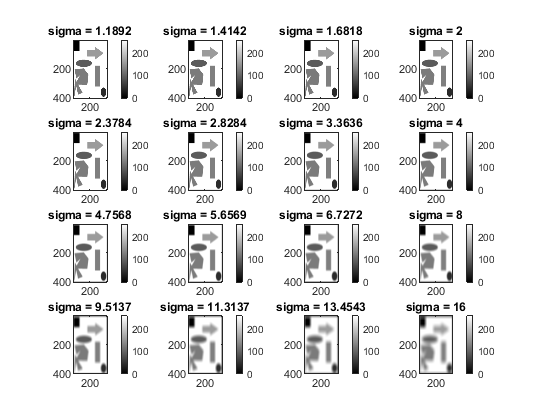

stride = 1;
subPlotShape = sqrt(upperLimit);
for i = 1:stride:upperLimit
    subplot(subPlotShape, subPlotShape, i);
    imagesc(gaussScaleArtificialIms(:, :, i+1));
    colorbar
    title("sigma = " + artificialSigmas(:, i+1));
end

## Question 2 Harris-Stevens [10 points]

For every pixel coordinate (**x_0**, **y_0**) we must compute the second moment matrix **M**, and then using **M** we can compute the equation det(**M**) − k(tr(**M**))^2 for k ≈ 0.1 with det(**M**) = M_11*M_22 - M_21*M_12 and tr(**M**) = M_11 + M_22.  Computing **M** requires that: for every (**x_0**,**y_0**) we need to calculate the image gradient; then calculate del(I)*transpose(del(I)); and then finally use those values and do a convolution with a gaussian function.

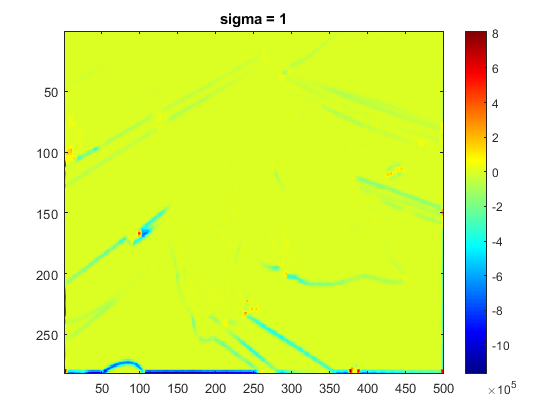

harrisStevensNaturalIms = harrisStevens(gaussScaleNaturalIms(:,:,1), naturalSigmas(1));

stride = 1;
for i = 2:stride:size(gaussScaleNaturalIms, 3)
    harrisStevensNaturalIms(:,:,i) = harrisStevens(gaussScaleNaturalIms(:,:,i), naturalSigmas(i));
end

figure
colormap(jet);
imagesc(harrisStevensNaturalIms(:,:,1));
colorbar
title("sigma = " + naturalSigmas(1));

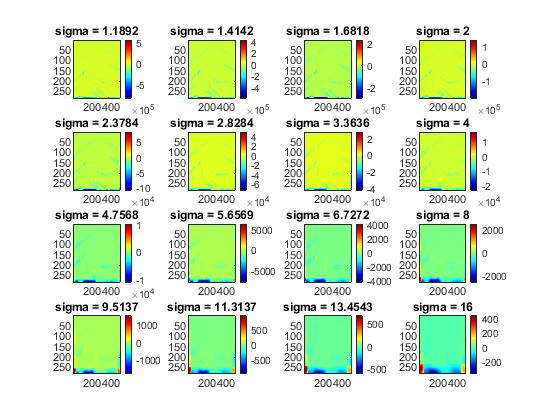

for i = 1:stride:size(harrisStevensNaturalIms, 3)-1
    subplot(subPlotShape, subPlotShape, i)
    imagesc(harrisStevensNaturalIms(:,:,i+1))
    colorbar
    title("sigma = " + naturalSigmas(i+1))
end

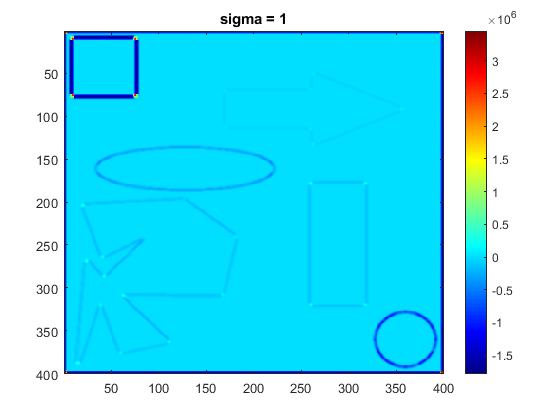

harrisStevensArtificialIms = harrisStevens(gaussScaleArtificialIms(:,:,1), artificialSigmas(1));

stride = 1;
for i = 2:stride:size(gaussScaleArtificialIms, 3)
    harrisStevensArtificialIms(:,:,i) = harrisStevens(gaussScaleArtificialIms(:,:,i), artificialSigmas(i));
end

figure
colormap(jet);
imagesc(harrisStevensArtificialIms(:,:,1));
colorbar
title("sigma = " + artificialSigmas(1));

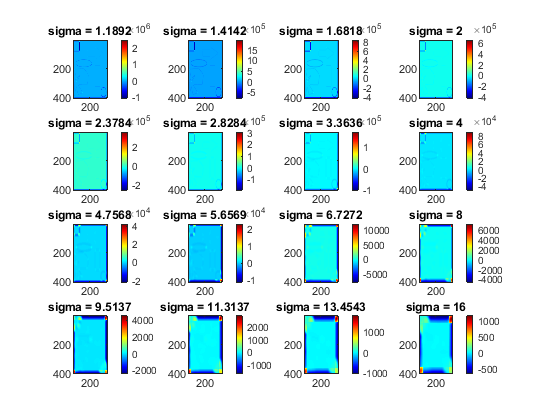

for i = 1:stride:size(harrisStevensArtificialIms, 3)-1
    subplot(subPlotShape, subPlotShape, i)
    imagesc(harrisStevensArtificialIms(:,:,i+1))
    colorbar
    title("sigma = " + artificialSigmas(i+1))
end

So by inspecting the results of both the artificial image and the natural image, the the locally distinctive points in the image are being highlighted by the operator, however by just looking at the colormap it's fairly difficult to see (could be due to the fact I'm partially color blind xD).  With increasing standard deviation, we see that the locally distinctive points become less and less accurate (the position becomes less sure and thus moves slightly) in the artificial image because there is no noise in the original base image.  However with the natural image the bluring of the gaussian actually helps to remove some of the noise in the image and thus the difficult to see locally distinctive points become a little easier to see.  However in both cases, blurring the image too much will reduce the detail of the image too much to the point where the only distinctive points are the corners of the image (ie no useful information).

## Question 3 Difference of Gaussians [10 points]

As instructed in the assignment pdf, the Difference of Gaussians scale space can be computed by just subtracting our neighboring sigmas in the Gaussian scale space.

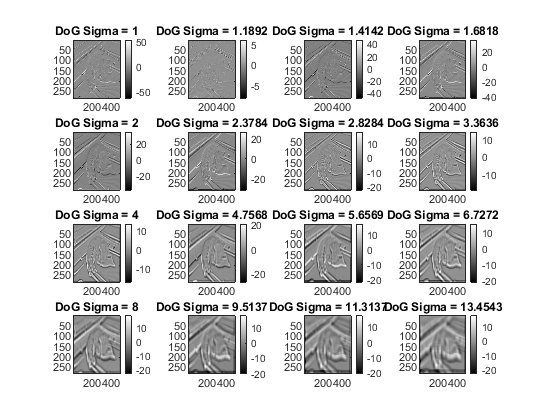

dOGScaleNaturalIms = zeros(size(gaussScaleNaturalIms, 1), size(gaussScaleNaturalIms, 2), size(gaussScaleNaturalIms, 3)-1);
dOGScaleArtificialIms = zeros(size(gaussScaleArtificialIms, 1), size(gaussScaleArtificialIms, 2), size(gaussScaleArtificialIms, 3)-1);

stride = 1;
for i = 1:stride:size(gaussScaleNaturalIms, 3)-1
    dOGScaleNaturalIms(:,:,i) = gaussScaleNaturalIms(:,:,i+1) - gaussScaleNaturalIms(:,:,i);
    dOGScaleArtificialIms(:,:,i) = gaussScaleArtificialIms(:,:,i+1) - gaussScaleArtificialIms(:,:,i);
end

figure
colormap(gray);
for i = 1:stride:size(dOGScaleNaturalIms, 3)
    subplot(subPlotShape, subPlotShape, i)
    imagesc(dOGScaleNaturalIms(:,:,i))
    colorbar
    title("DoG Sigma = " + naturalSigmas(i))
end

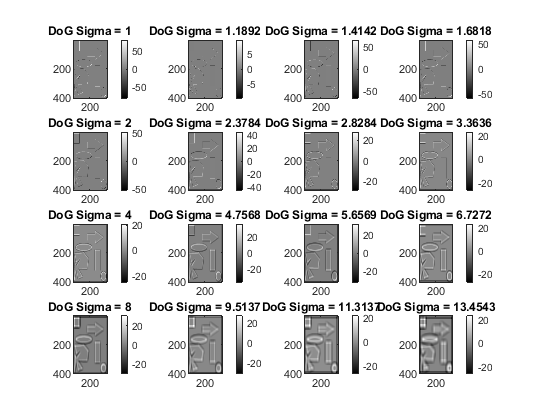

figure
colormap(gray);
for i = 1:stride:size(dOGScaleArtificialIms, 3)
    subplot(subPlotShape, subPlotShape, i)
    imagesc(dOGScaleArtificialIms(:,:,i))
    colorbar
    title("DoG Sigma = " + artificialSigmas(i))
end

Across scale space, the Difference of Gaussian's reveal a similar pattern as we might expect, wherein at lower sigma, the image with no noise is objectively more accurate at determining the zero crossings compared to at higher sigma, however with increasing sigma, the DoG filter accentuates the correct zero crossings and blurs the noise which masks the false zero crossings that pop up in the natural image.

## Question 4 SIFT Keypoint detection [20 points] 

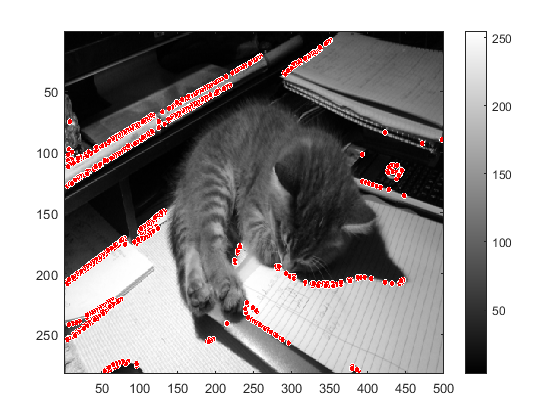

absoluteThreshold = 20;

locallyDistinctivePointsNatural = siftKeypoints(dOGScaleNaturalIms, naturalSigmas, absoluteThreshold);
locallyDistinctivePointsArtificial = siftKeypoints(dOGScaleArtificialIms, artificialSigmas, absoluteThreshold);

figure
colormap(gray);
imagesc(naturalIm);
colorbar
stride = 1;
for i = 1:stride:size(locallyDistinctivePointsNatural, 1)
    viscircles([locallyDistinctivePointsNatural(i, 1) locallyDistinctivePointsNatural(i, 2)], 1);
end

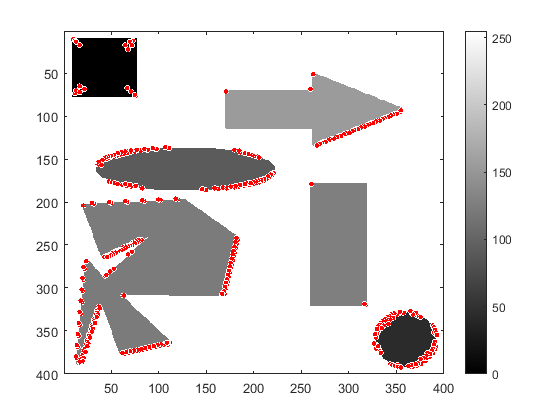

figure
colormap(gray);
imagesc(artificialIm);
colorbar
stride = 1;
for i = 1:stride:size(locallyDistinctivePointsArtificial, 1)
    viscircles([locallyDistinctivePointsArtificial(i, 1) locallyDistinctivePointsArtificial(i, 2)], 1);
end

So, as can be seen above, some keypoints of the images are being correctly determined however if we were to want more accurate results, the "Absolute Threshold" should be replaced with a proportional threshold wherein the cutoff is a percentage which is the multiplied in onto the range of intensity values for each individual image (ie each DoG scale space would end up with a different threshold cutoff).

## Question 5 Hessian constraint [20 points]

According to Lowe's paper: **D**(x, y, σ) = (**G**(x, y, kσ) − **G**(x, y, σ)) ∗ **I**(x, y) **;** **H** = [**D**xx **D**xy; **D**xy **D**yy] **;** Tr(**H**) = **D**xx + **D**yy **;** Det(**H**) = **D**xx**D**yy − (**D**xy)^2 **;** (Tr(**H)**^2) / Det(**H**) = ((**r** + 1)^2) / **r** where **r** is the ratio of the eigenvalues of **H**. So evaluating (Tr(**H)**^2) / Det(**H**) < ((**r** + 1)^2) / **r **for a desired ratio (paper used **r** = 10) we can check for well localized keypoints as opposed to keypoints that fall along edges, etc.  Seen as our dOGScaleIms are exactly **D**(x, y, σ), we simply need to approximate **D**xx, **D**xy, and **D**yy, namely we need a convolution filter that approximates the second derivative wrt x, one that approximates the second derivative wrt y, and one that approximates the partial x followed by partial y.  For the **D**xy term, because **D**xy = d/dy(d**D**/dx), we can simply use the same approximations for derivatives used in Question 2 for the Harris Stevens operator, namely d**D/**dxFilter = [-0.5 0 0.5], and d**D/**dyFilter = [-0.5; 0; 0.5].  For the **D**xx and **D**yy terms we can simplify our computation by taking the direct approximation for a second order derivative, namely d**D**/dxFilter = [1 -2 1], and d**D**/dyFilter = [1; -2; 1].

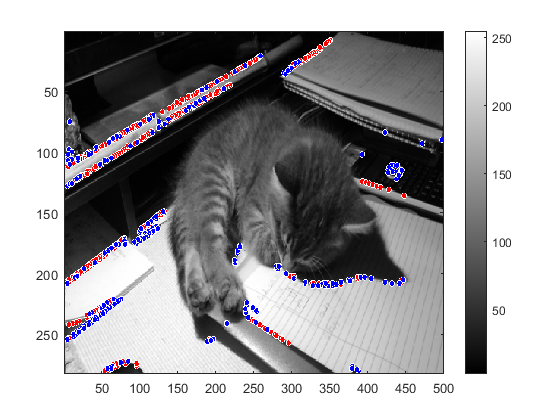

r = 10;
hessianApprovedLocallyDistinctPointsNatural = hessianApproval(dOGScaleNaturalIms, locallyDistinctivePointsNatural, r);
r = 3;
hessianApprovedLocallyDistinctPointsArtificial = hessianApproval(dOGScaleArtificialIms, locallyDistinctivePointsArtificial, r);

figure
colormap(gray);
imagesc(naturalIm);
colorbar
stride = 1;
for i = 1:stride:size(locallyDistinctivePointsNatural, 1)
    viscircles([locallyDistinctivePointsNatural(i, 1) locallyDistinctivePointsNatural(i, 2)], 1);
end
for i = 1:stride:size(hessianApprovedLocallyDistinctPointsNatural, 1)
    viscircles([hessianApprovedLocallyDistinctPointsNatural(i, 1) hessianApprovedLocallyDistinctPointsNatural(i, 2)], 1, 'Color', 'blue');
end

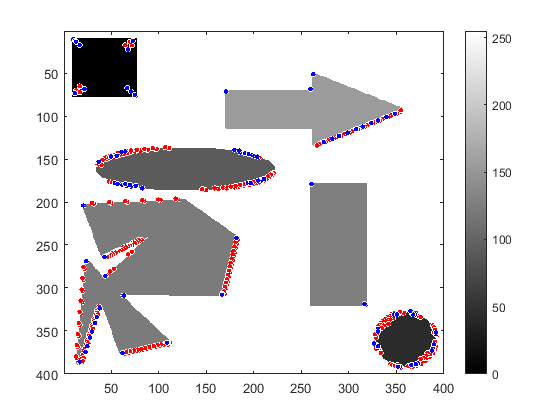

figure
colormap(gray);
imagesc(artificialIm);
colorbar
stride = 1;
for i = 1:stride:size(locallyDistinctivePointsArtificial, 1)
    viscircles([locallyDistinctivePointsArtificial(i, 1) locallyDistinctivePointsArtificial(i, 2)], 1);
end
for i = 1:stride:size(hessianApprovedLocallyDistinctPointsArtificial, 1)
    viscircles([hessianApprovedLocallyDistinctPointsArtificial(i, 1) hessianApprovedLocallyDistinctPointsArtificial(i, 2)], 1, 'Color','blue');
end

The natural image behaves well for r = 10 (as Lowe's paper suggested), the hessian drastically reducing the number of keypoints (700 points to 250 points) .  The artificial image however needed a much lower ratio in order to get comparable results, namely r = 3 gave us a reduction from 550 to 100.  This is as always a result of the artificial image having no noise in the image.

## Question 6 SIFT feature dominant orientation [20 points]

The Sobel-Feldman operator: **G**_x = conv2(**I**, [1 0 -1; 2 0 -2; 1 0 -1]); **G**_y = conv2(**I**, [1 2 1; 0 0 0; -1 -2 -1]); computes an approximation of the x and y components of the gradient of an image at every point, and with both y increasing downwards and the trigonometric relation **Theta** = arctan(**G**_y/**G**_x) we can define a clockwise positive angle for for the gradient at every point in the image.  From there, given a keypoint (**x**,**y**,**sigma**) we can calculate an orientation histogram for the neighborhood defined by a gaussian with a standard deviation of 1.5***sigma **where the magnitude of the gradient vector times by it's gaussian weight is what's added to the bin corresponding to the **Theta** for this keypoint.

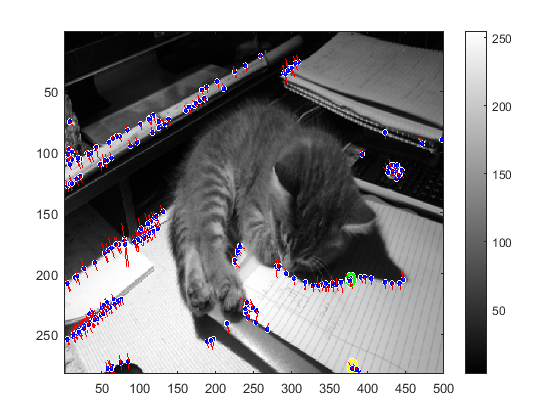

[finalLocallyDistinctKeypointsNatural, gradientHistogramsNatural] = dominantOrientation(dOGScaleNaturalIms, naturalSigmas, hessianApprovedLocallyDistinctPointsNatural);
[finalLocallyDistinctKeypointsArtificial, gradientHistogramsArtificial] = dominantOrientation(dOGScaleArtificialIms, artificialSigmas, hessianApprovedLocallyDistinctPointsArtificial);

figure
colormap(gray);
imagesc(naturalIm);
colorbar
stride = 1;
for i = 1:stride:size(finalLocallyDistinctKeypointsNatural, 1)
    if i == round(size(finalLocallyDistinctKeypointsNatural, 1)/4)
        viscircles([finalLocallyDistinctKeypointsNatural(i, 1) finalLocallyDistinctKeypointsNatural(i, 2)], 5, 'Color', 'green');
    elseif i == round(3*size(finalLocallyDistinctKeypointsNatural, 1)/4)
        viscircles([finalLocallyDistinctKeypointsNatural(i, 1) finalLocallyDistinctKeypointsNatural(i, 2)], 5, 'Color', 'yellow');
    else
        viscircles([finalLocallyDistinctKeypointsNatural(i, 1) finalLocallyDistinctKeypointsNatural(i, 2)], 1, 'Color', 'blue');
    end
    lineDist = 4*naturalSigmas(finalLocallyDistinctKeypointsNatural(i,3));
    xValues = [finalLocallyDistinctKeypointsNatural(i,1)   finalLocallyDistinctKeypointsNatural(i,1) + lineDist*cosd(finalLocallyDistinctKeypointsNatural(i, 4))];
    yValues = [finalLocallyDistinctKeypointsNatural(i,2)   finalLocallyDistinctKeypointsNatural(i,2) + lineDist*sind(finalLocallyDistinctKeypointsNatural(i, 4))];
    line(xValues, yValues, 'Color', 'red');
end

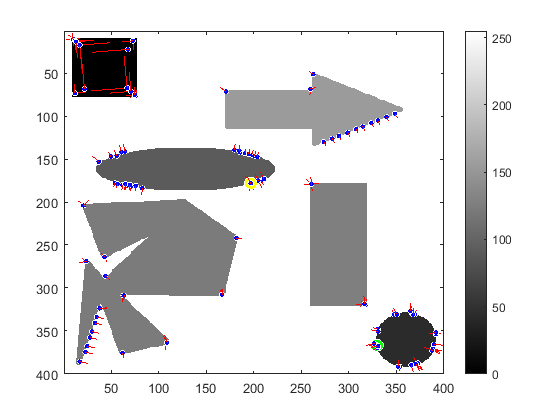

figure
colormap(gray);
imagesc(artificialIm);
colorbar
stride = 1;
for i = 1:stride:size(finalLocallyDistinctKeypointsArtificial, 1)
    if i == round(size(finalLocallyDistinctKeypointsArtificial, 1)/4)
        viscircles([finalLocallyDistinctKeypointsArtificial(i, 1) finalLocallyDistinctKeypointsArtificial(i, 2)], 5, 'Color', 'green');
    elseif i == round(3*size(finalLocallyDistinctKeypointsArtificial, 1)/4)
        viscircles([finalLocallyDistinctKeypointsArtificial(i, 1) finalLocallyDistinctKeypointsArtificial(i, 2)], 5, 'Color', 'yellow');
    else
        viscircles([finalLocallyDistinctKeypointsArtificial(i, 1) finalLocallyDistinctKeypointsArtificial(i, 2)], 1, 'Color', 'blue');
    end
    lineDist = 4*artificialSigmas(finalLocallyDistinctKeypointsArtificial(i,3));
    xValues = [finalLocallyDistinctKeypointsArtificial(i,1)   finalLocallyDistinctKeypointsArtificial(i,1) + lineDist*cosd(finalLocallyDistinctKeypointsArtificial(i, 4))];
    yValues = [finalLocallyDistinctKeypointsArtificial(i,2)   finalLocallyDistinctKeypointsArtificial(i,2) + lineDist*sind(finalLocallyDistinctKeypointsArtificial(i, 4))];
    line(xValues, yValues, 'Color', 'red');
end

All of the line lengths were a little too small at 2sigma length so instead I'm using a 4sigma length.  All of the directions seem to make sense to what you'd expect for the gradients.

## Question 7 Scale Invariance [10 points]

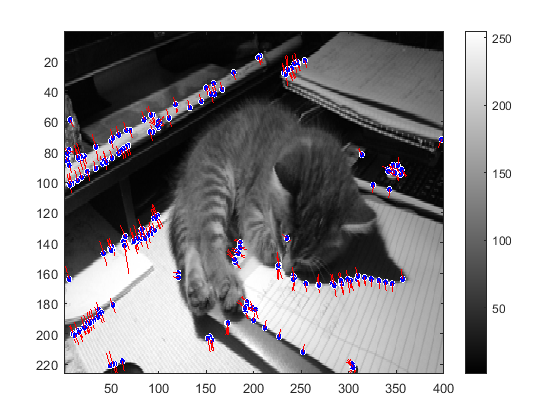

scaledNaturalIm = imresize(naturalIm, 0.8);
scaledArtificialIm = imresize(artificialIm, 1.2);

upperLimit = 16;
sigmaNot = 1;
[gaussScaleScaledNaturalIms, scaledNaturalSigmas] = gaussianScaleSpace(scaledNaturalIm, upperLimit, sigmaNot);
[gaussScaleScaledArtificialIms, scaledArtificialSigmas] = gaussianScaleSpace(scaledArtificialIm, upperLimit, sigmaNot);

dOGScaleScaledNaturalIms = zeros(size(gaussScaleScaledNaturalIms, 1), size(gaussScaleScaledNaturalIms, 2), size(gaussScaleScaledNaturalIms, 3)-1);
dOGScaleScaledArtificialIms = zeros(size(gaussScaleScaledArtificialIms, 1), size(gaussScaleScaledArtificialIms, 2), size(gaussScaleScaledArtificialIms, 3)-1);

stride = 1;
for i = 1:stride:size(gaussScaleScaledNaturalIms, 3)-1
    dOGScaleScaledNaturalIms(:,:,i) = gaussScaleScaledNaturalIms(:,:,i+1) - gaussScaleScaledNaturalIms(:,:,i);
    dOGScaleScaledArtificialIms(:,:,i) = gaussScaleScaledArtificialIms(:,:,i+1) - gaussScaleScaledArtificialIms(:,:,i);
end

absoluteThreshold = 20;

locallyDistinctivePointsScaledNatural = siftKeypoints(dOGScaleScaledNaturalIms, scaledNaturalSigmas, absoluteThreshold);
locallyDistinctivePointsScaledArtificial = siftKeypoints(dOGScaleScaledArtificialIms, scaledArtificialSigmas, absoluteThreshold);

r = 10;
hessianApprovedLocallyDistinctPointsScaledNatural = hessianApproval(dOGScaleScaledNaturalIms, locallyDistinctivePointsScaledNatural, r);
r = 3;
hessianApprovedLocallyDistinctPointsScaledArtificial = hessianApproval(dOGScaleScaledArtificialIms, locallyDistinctivePointsScaledArtificial, r);

[finalLocallyDistinctKeypointsScaledNatural, gradientHistogramsScaledNatural] = dominantOrientation(dOGScaleScaledNaturalIms, scaledNaturalSigmas, hessianApprovedLocallyDistinctPointsScaledNatural);
[finalLocallyDistinctKeypointsScaledArtificial, gradientHistogramsScaledArtificial] = dominantOrientation(dOGScaleScaledArtificialIms, scaledArtificialSigmas, hessianApprovedLocallyDistinctPointsScaledArtificial);

figure
colormap(gray);
imagesc(scaledNaturalIm);
colorbar
stride = 1;
for i = 1:stride:size(finalLocallyDistinctKeypointsScaledNatural, 1)
    viscircles([finalLocallyDistinctKeypointsScaledNatural(i, 1) finalLocallyDistinctKeypointsScaledNatural(i, 2)], 1, 'Color', 'blue');
    lineDist = 4*scaledNaturalSigmas(finalLocallyDistinctKeypointsScaledNatural(i,3));
    xValues = [finalLocallyDistinctKeypointsScaledNatural(i,1)   finalLocallyDistinctKeypointsScaledNatural(i,1) + lineDist*cosd(finalLocallyDistinctKeypointsScaledNatural(i, 4))];
    yValues = [finalLocallyDistinctKeypointsScaledNatural(i,2)   finalLocallyDistinctKeypointsScaledNatural(i,2) + lineDist*sind(finalLocallyDistinctKeypointsScaledNatural(i, 4))];
    line(xValues, yValues, 'Color', 'red');
end

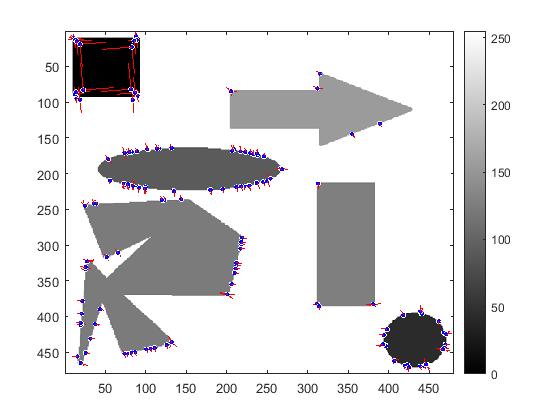


figure
colormap(gray);
imagesc(scaledArtificialIm);
colorbar
stride = 1;
for i = 1:stride:size(finalLocallyDistinctKeypointsScaledArtificial, 1)
    viscircles([finalLocallyDistinctKeypointsScaledArtificial(i, 1) finalLocallyDistinctKeypointsScaledArtificial(i, 2)], 1, 'Color', 'blue');
    lineDist = 4*scaledArtificialSigmas(finalLocallyDistinctKeypointsScaledArtificial(i,3));
    xValues = [finalLocallyDistinctKeypointsScaledArtificial(i,1)   finalLocallyDistinctKeypointsScaledArtificial(i,1) + lineDist*cosd(finalLocallyDistinctKeypointsScaledArtificial(i, 4))];
    yValues = [finalLocallyDistinctKeypointsScaledArtificial(i,2)   finalLocallyDistinctKeypointsScaledArtificial(i,2) + lineDist*sind(finalLocallyDistinctKeypointsScaledArtificial(i, 4))];
    line(xValues, yValues, 'Color', 'red');
end

Unfortunately in my artificial image we can see that the keypoints are different at a different scale, but not so extremely that you would end up with completely off results, only perhaps a slight skew.  And this difference is even less noticeable in the natural image.  This likely means somewhere along the lines I made a slight error.  Nothing large enough to make the results misbehave entirely, but enough to cause slight skews.

## Functions

### Question 1

function [gaussScaleIms, sigmas] = gaussianScaleSpace(im, upperLimit, sigmaNot)

% The sigma = sigmaNot case
sigma = sigmaNot;
g = fspecial('gaussian', round(3*sigma), sigma);
gaussScaleIm = conv2(im, g, 'same');
gaussScaleIms = gaussScaleIm;
sigmas = sigma;

% The rest of the sigma's
m = 4;
k_max = sqrt(upperLimit) - 1;
stride = 1;
plotNum = 2;
for k = 0:stride:k_max
    for h = 1:stride:m
        sigma = (2^((h/m)+k))*sigmaNot;
        g = fspecial('gaussian', round(3*sigma), sigma);
        gaussScaleIm = conv2(im, g, 'same');
        gaussScaleIms(:, :, plotNum) = gaussScaleIm;
        sigmas(:, plotNum) = sigma;
        plotNum = plotNum + 1;
    end
end

end

### Question 2

function harrisStevens = harrisStevens(im, sigma)

dIdxFilter = [-0.5 0 0.5];
dIdyFilter = [-0.5; 0; 0.5];

dIdxGaussScaleIm = conv2(im, dIdxFilter, 'same');
dIdyGaussScaleIm = conv2(im, dIdyFilter, 'same');

%del(I)*transpose(del(I))
M_11 = dIdxGaussScaleIm.*dIdxGaussScaleIm;
M_12 = dIdxGaussScaleIm.*dIdyGaussScaleIm;
%M_21 = M_12;
M_22 = dIdyGaussScaleIm.*dIdyGaussScaleIm;

sigma_window = sigma * 2;
k = 0.1;
g = fspecial('gaussian', round(3*sigma_window), sigma_window);
M_11 = conv2(M_11, g, 'same');
M_12 = conv2(M_12, g, 'same');
M_22 = conv2(M_22, g, 'same');
harrisStevens = (M_11.*M_22 - M_12.*M_12) - k.*(M_11 + M_22).^2;

end

### Question 4

function locallyDistinctivePoints = siftKeypoints(dOGScaleIms, sigmas, absoluteThreshold)
stride = 1;
numPoints = 1;
locallyDistinctivePoints = zeros(1000,4);
for k = 2:stride:size(dOGScaleIms, 3)-1
    for i = round(2*sigmas(k))+1:stride:size(dOGScaleIms(:,:,k), 1) - round(2*sigmas(k))+1
        for j = round(2*sigmas(k))+1:stride:size(dOGScaleIms(:,:,k), 2) - round(2*sigmas(k))+1
            max = true;
            min = true;
            for c = k-1:stride:k+1
                for a = i-1:stride:i+1
                    for b = j-1:stride:j+1
                        if a ~= i || b ~= j || c ~= k
                            max = max && (dOGScaleIms(i,j,k) > dOGScaleIms(a,b,c));
                            min = min && (dOGScaleIms(i,j,k) < dOGScaleIms(a,b,c));
                        end
                    end
                end
            end
            if (max || min) && (abs(dOGScaleIms(i,j,k)) > absoluteThreshold)
                locallyDistinctivePoints(numPoints,:) = [j i k 0]; %Storing as (x,y,sigmasIndex,orientation)
                numPoints = numPoints + 1;
            end
        end
    end
end
if size(locallyDistinctivePoints, 1) >= numPoints-1
    locallyDistinctivePoints = locallyDistinctivePoints(1:numPoints-1, :);
end
end

### Question 5

function hessianApprovedLocallyDistinctPoints = hessianApproval(dOGScaleIms, locallyDistinctivePoints, ratio)
d2Ddx2 = [1 -2 1];
d2Ddy2 = [1; -2; 1];
dDdx = [-0.5 0 0.5];
dDdy = [-0.5; 0; 0.5];

DNatxx = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later
DNatyy = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later
DNatxy = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later

stride = 1;
for k = 2:stride:size(dOGScaleIms, 3)-1
    DNatxx(:,:,k) = conv2(dOGScaleIms(:,:,k), d2Ddx2, 'same');
    DNatyy(:,:,k) = conv2(dOGScaleIms(:,:,k), d2Ddy2, 'same');
    DNatxy(:,:,k) = conv2(conv2(dOGScaleIms(:,:,k), dDdx, 'same'), dDdy, 'same');
end

numPoints = 1;
hessianApprovedLocallyDistinctPoints = zeros(size(locallyDistinctivePoints, 1), size(locallyDistinctivePoints, 2));
for i = 1:stride:size(locallyDistinctivePoints, 1)
    x = locallyDistinctivePoints(i, 1);
    y = locallyDistinctivePoints(i, 2);
    k = locallyDistinctivePoints(i, 3);
    if (((DNatxx(y,x,k) + DNatyy(y,x,k))^2) / (DNatxx(y,x,k)*DNatyy(y,x,k) - (DNatxy(y,x,k))^2)) < (((ratio + 1)^2) / ratio)
        hessianApprovedLocallyDistinctPoints(numPoints, :) = locallyDistinctivePoints(i, :);
        numPoints = numPoints + 1;
    end
end
if size(hessianApprovedLocallyDistinctPoints, 1) >= numPoints-1
    hessianApprovedLocallyDistinctPoints = hessianApprovedLocallyDistinctPoints(1:numPoints-1, :);
end
end

### Question 6

function [finalLocallyDistinctKeypoints, gradientHistograms] = dominantOrientation(dOGScaleIms, sigmas, hessianApprovedLocallyDistinctPoints)
gradient_x = [1 0 -1; 2 0 -2; 1 0 -1];
gradient_y = [1 2 1; 0 0 0; -1 -2 -1];

numAngleBins = 36;
binWidth = 360 / numAngleBins;
G_x = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later
G_y = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later
G_thetas = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later
G = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1); %leaving room for 1 empty index for convenience of indexing later
G_thetaBinned = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1, numAngleBins); %leaving room for 1 empty index for convenience of indexing later
G_thetaBinnedWeighted = zeros(size(dOGScaleIms, 1), size(dOGScaleIms, 2), size(dOGScaleIms, 3)-1, numAngleBins); %leaving room for 1 empty index for convenience of indexing later

stride = 1;
for k = 2:stride:size(dOGScaleIms, 3)-1
    G_x(:,:,k) = conv2(dOGScaleIms(:,:,k), gradient_x, 'same');
    G_y(:,:,k) = conv2(dOGScaleIms(:,:,k), gradient_y, 'same');
    G(:,:,k) = sqrt(G_x(:,:,k).^2 + G_y(:,:,k).^2); %Is there a way to avoid this sqrt?
    for i = 1:stride:size(G_x,1)
        for j = 1:stride:size(G_x,2)
            if G_x(i,j,k) ~= 0
                G_thetas(i,j,k) = mod(atan2d(G_y(i,j,k), G_x(i,j,k)), 360);
            elseif G_y(i,j,k) >= 0
                G_thetas(i,j,k) = 90;
            else
                G_thetas(i,j,k) = 270;
            end
            binTheta = floor(mod(G_thetas(i,j,k) + 5, 360) / binWidth) + 1;
            G_thetaBinned(i,j,k,binTheta) = G(i,j,k);
        end
    end
    sigma = 1.5*sigmas(k);
    g = fspecial('gaussian', round(3*sigma), sigma);
    for i = 1:stride:numAngleBins
        G_thetaBinnedWeighted(:,:,k,i) = conv2(G_thetaBinned(:,:,k, i), g, 'same');
    end
end

gradientHistograms = zeros(size(hessianApprovedLocallyDistinctPoints, 1), numAngleBins);
for i = 1:stride:size(hessianApprovedLocallyDistinctPoints, 1)
    x = hessianApprovedLocallyDistinctPoints(i, 1);
    y = hessianApprovedLocallyDistinctPoints(i, 2);
    k = hessianApprovedLocallyDistinctPoints(i, 3);
    for j = 1:stride:numAngleBins
        gradientHistograms(i, j) = G_thetaBinnedWeighted(y, x, k, j);
    end
end

finalLocallyDistinctKeypoints = zeros(size(hessianApprovedLocallyDistinctPoints, 1)*2, 4);
numPoints = 1;
for i = 1:stride:size(gradientHistograms, 1)
    dominantGradient = max(gradientHistograms(i, :));
    for j = 1:stride:numAngleBins
        if gradientHistograms(i, j) > 0.8 * dominantGradient
            finalLocallyDistinctKeypoints(numPoints, 1) = hessianApprovedLocallyDistinctPoints(i, 1);
            finalLocallyDistinctKeypoints(numPoints, 2) = hessianApprovedLocallyDistinctPoints(i, 2);
            finalLocallyDistinctKeypoints(numPoints, 3) = hessianApprovedLocallyDistinctPoints(i, 3);
            finalLocallyDistinctKeypoints(numPoints, 4) = mod((j - 1)*binWidth - 5, 360);
            numPoints = numPoints + 1;
        end
    end
end
if size(finalLocallyDistinctKeypoints, 1) >= numPoints-1
    finalLocallyDistinctKeypoints = finalLocallyDistinctKeypoints(1:numPoints-1, :);
end

end